# Chapter 1: Calibration of Output Devices

%% 1. Load Necessary Data
clear; clc; close all;

% Load spectral data, illuminants, and color matching functions
load('chips20.mat');  % Spectral reflectance data
load('illum.mat');    % Spectral data for different illuminants
load('xyz.mat');      % Color Matching Functions (CMFs)
load('TRC_display.mat'); % Tone reproduction curves for display
load('DLP.mat');      % Spectral data for DLP projector primaries

% Define wavelength range (400:5:700 nm)
wavelengths = 400:5:700; 

## 1.1: Plot TRCs (Tone-Reproduction Curves) for RGB channels

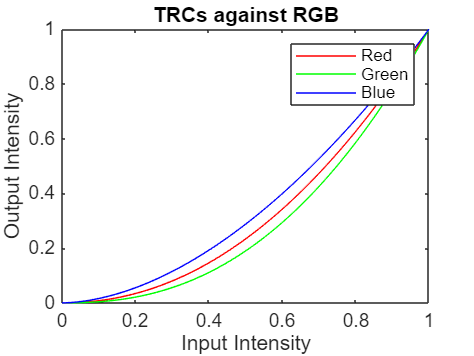

% Tone Reproduction curves show the relationship between luminence and
% color and display luminance
figure;
plot(0:0.01:1, TRCr, 'r', 0:0.01:1, TRCg, 'g', 0:0.01:1, TRCb, 'b');
title('Tone Reproduction Curves (TRCs)');
xlabel('Input Intensity');
ylabel('Output Intensity');
title('TRCs against RGB');
legend('Red', 'Green', 'Blue');


% Answer: The display will apear more blue and less green.

## 1.2: Linearization using interpolation (Check hints for inverse interpolation)

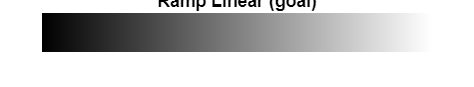

% Load images
load('Ramp_linear.mat');
load('Ramp_display.mat');

% Show Ramp_linear
figure;
imshow(Ramp_linear);
title('Ramp Linear (goal)');

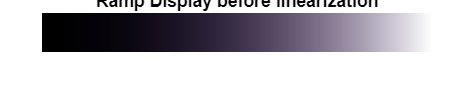


% Show Ramp_display before linearization
figure;
imshow(Ramp_display);
title('Ramp Display before linearization');

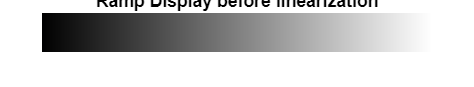


% linearization to image
Ramp_linearized(:,:,1) = interp1(TRCr, 0:0.01:1, Ramp_display(:,:,1), 'pchip'); % interploation from tips
Ramp_linearized(:,:,2) = interp1(TRCg, 0:0.01:1, Ramp_display(:,:,2), 'pchip');
Ramp_linearized(:,:,3) = interp1(TRCb, 0:0.01:1, Ramp_display(:,:,3), 'pchip');

% Display linearized image
figure;
imshow(Ramp_linearized);
title('Ramp Display before linearization');


% Answer: Look at result

## 1.3: Gamma correction

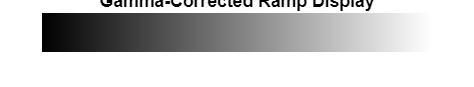

% Define gamma
gamma_R = 2.1; 
gamma_G = 2.4;
gamma_B = 1.8;

% Gamma correction using eq 4, can't make Dmax work
Ramp_gamma_corrected(:,:,1) = Ramp_display(:,:,1) .^ (1/gamma_R);
Ramp_gamma_corrected(:,:,2) = Ramp_display(:,:,2) .^ (1/gamma_G);
Ramp_gamma_corrected(:,:,3) = Ramp_display(:,:,3) .^ (1/gamma_B);

% Display the gamma-corrected image
figure;
imshow(Ramp_gamma_corrected);
title('Gamma-Corrected Ramp Display');


% Answer: Look at result

# Chapter 2: Spectral Forward Model of the Output Device

## 2.1: Load and plot spectral data for DLP projector

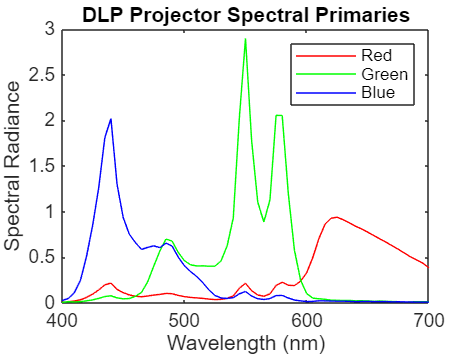

figure;
plot(wavelengths, DLP(:,1), 'r', wavelengths, DLP(:,2), 'g', wavelengths, DLP(:,3), 'b');
title('DLP Projector Spectral Primaries');
xlabel('Wavelength (nm)');
ylabel('Spectral Radiance');
legend('Red', 'Green', 'Blue');


% Answer: The projector will apear more green, and less red. Especially
% since the red is more spread out over light to darker red. 

## 2.2: Compute spectral output for raw camera data

load('RGB_raw.mat'); % Raw RGB data
load('XYZ_ref.mat');

SRGB = DLP * RGB_raw; % Compute projected spectra, Eq. 2

% Convert to XYZ, like in lab1
k = 100 / sum(xyz(:,2) .* CIED65'); % Normalization factor
XYZ_projector = k * (xyz' * SRGB);

% Compute color difference (delta Eab)
[LAB_ref_L, LAB_ref_a, LAB_ref_b] = xyz2lab(XYZ_ref(1,:), XYZ_ref(2,:), XYZ_ref(3,:)); % XYZ ref to Lab
[LAB_projector_L, LAB_projector_a, LAB_projector_b] = xyz2lab(XYZ_projector(1,:), XYZ_projector(2,:), XYZ_projector(3,:)); % projector XYZ to lab
deltaE_raw = sqrt((LAB_projector_L - LAB_ref_L).^2 + (LAB_projector_a - LAB_ref_a).^2 + (LAB_projector_b - LAB_ref_b).^2);    % compute delta

% Display result
disp('Raw Camera Input to Projector:')

Raw Camera Input to Projector:


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_raw));

Mean delta Eab: 22.35


fprintf('Max delta Eab: %.2f\n', max(deltaE_raw));

Max delta Eab: 51.64


## 2.3: Compute spectral output for calibrated camera data

load('RGB_cal.mat'); % Raw RGB data

% Compute projected spectra with calibrated RGB
SRGB_calibrated = DLP * RGB_cal;

% Convert to XYZ
XYZ_projected_calibrated = k * (xyz' * SRGB_calibrated);
[LAB_projected_calibrated_L, LAB_projected_calibrated_a, LAB_projected_calibrated_b]  = xyz2lab(XYZ_projected_calibrated(1,:), XYZ_projected_calibrated(2,:), XYZ_projected_calibrated(3,:));

% Compute delta Eab color difference
deltaE_calibrated = sqrt((LAB_projected_calibrated_L - LAB_ref_L).^2 + (LAB_projected_calibrated_a - LAB_ref_a).^2 + (LAB_projected_calibrated_b - LAB_ref_b).^2);    % compute delta

% Display results
disp('Calibrated Camera Input to Projector:')

Calibrated Camera Input to Projector:


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_calibrated));

Mean delta Eab: 16.92


fprintf('Max delta Eab: %.2f\n', max(deltaE_calibrated));

Max delta Eab: 33.54


# Chapter 3: Inverse Characterization of the Output Device

## 3.1: Compute XYZ Values for Projector Primaries

XYZ_R = k * (xyz' * DLP(:,1));
XYZ_G = k * (xyz' * DLP(:,2));
XYZ_B = k * (xyz' * DLP(:,3));
ACRT = [XYZ_R, XYZ_G, XYZ_B]; % Eq. (3)

% Compute inverse transformation matrix
ACRT_inv = inv(ACRT)

ACRT_inv =     0.0438   -0.0266   -0.0062
   -0.0108    0.0182    0.0001
   -0.0032   -0.0001    0.0115



% Answer: That is certainly a 3x3 matrix

## 3.2: Full Color Management Workflow

load('XYZ_est.mat'); % Load calibrated camera data from Lab 1 section 3.4 & 3.5??
XYZ_input = (ACRT_inv * XYZ_est)'; % Corrected matrix multiplication

% Convert XYZ to projector RGB
RGB_projector = (ACRT_inv * XYZ_est)';

% Compute final projected spectra
SRGB_projector = DLP * RGB_projector';

% Convert to XYZ
XYZ_projector_final = k * (xyz' * SRGB_projector);
[LAB_projector_final_L, LAB_projector_final_a, LAB_projector_final_b] = xyz2lab(XYZ_projector_final(1,:), XYZ_projector_final(2,:), XYZ_projector_final(3,:));

% Compute delta Eab
deltaE_final = sqrt((LAB_projector_final_L - LAB_ref_L).^2 + (LAB_projector_final_a - LAB_ref_a).^2 + (LAB_projector_final_b - LAB_ref_b).^2);    % compute delta

disp("Final Color Managed Output")

Final Color Managed Output


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_final));

Mean delta Eab: 1.02


fprintf('Max delta Eab: %.2f\n', max(deltaE_final));

Max delta Eab: 3.11



% Probably wrong...

## 3.3: Analyze Projector RGB Values (D'R, D'G, D'B)

% Check if any values are out of bounds
disp("Display RGB projector")

Display RGB projector


disp(RGB_projector)

    0.7491    0.5099    0.4799
    0.3818    0.1543    0.2366
    0.0742    0.0773    0.1327
    0.1615    0.1217    0.1859
    0.0060    0.4973    0.4524
    0.2044    0.3095    0.3594
    0.7004    0.4826   -0.0630
    0.1009    0.0399    0.0501
    0.5019    0.3035   -0.0584
    0.0495    0.0311    0.0355
    0.2964    0.0337    0.1350
    0.3718    0.1004    0.0566
    0.2326    0.0645    0.0862
    0.1363    0.2549    0.0218
    0.1461    0.2897    0.6421
    0.2187    0.0426    0.1578
   -0.0912    0.3511    0.5430
    0.4061    0.1029    0.0088
    0.6730    0.5939    0.0092
    0.3704    0.2922    0.3111



out_of_bounds = (RGB_projector < 0) | (RGB_projector > 1);

% Display the number of out-of-range values
num_out_of_bounds = sum(out_of_bounds(:));
fprintf('Number of out-of-bounds RGB values: %d\n', num_out_of_bounds);% If not 0, some are out of bounds?

Number of out-of-bounds RGB values: 3



% Answer: Why? Due to inverse multiplication.

## 3.4: Clip RGB Values to [0,1] Range

% Clip RGB Values to [0,1] Range
RGB_projector_clipped = min(max(RGB_projector, 0), 1);

% Compute final output spectra with clipped values, like 3.2
SRGB_clipped = DLP * RGB_projector_clipped';
XYZ_projected_clipped = k * (xyz' * SRGB_clipped);
[LAB_projected_clipped_L, LAB_projected_clipped_a, LAB_projected_clipped_b] = xyz2lab(XYZ_projected_clipped(1,:), XYZ_projected_clipped(2,:), XYZ_projected_clipped(3,:));

% Compute new delta Eab after clipping
deltaE_clipped = sqrt((LAB_projected_clipped_L - LAB_ref_L).^2 + (LAB_projected_clipped_a - LAB_ref_a).^2 + (LAB_projected_clipped_b - LAB_ref_b).^2);    % compute delta

disp("After Clipping RGB to [0,1]")

After Clipping RGB to [0,1]


fprintf('Mean delta Eab: %.2f\n', mean(deltaE_clipped));

Mean delta Eab: 2.84


fprintf('Max delta Eab: %.2f\n', max(deltaE_clipped));

Max delta Eab: 17.87



% Same max but diffrent mean comparing 3.2

## 3.5: Compare Projector Gamut with sRGB

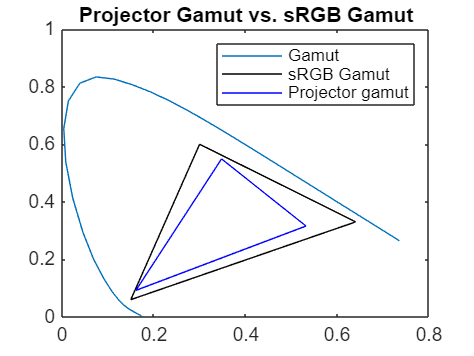

% Gamut = the complete range or scope of something, aka color in this case (färgomfång) 
figure;
plot_chrom_sRGB(ACRT);
legend('Gamut', 'sRGB Gamut', 'Projector gamut');
title('Projector Gamut vs. sRGB Gamut');

% Projector has smaller gamut that all off SRGB, espehially in the red
% range as expected in 2.1

## 3.6 Chromaticity Analysis of a Reproduced Color Sample

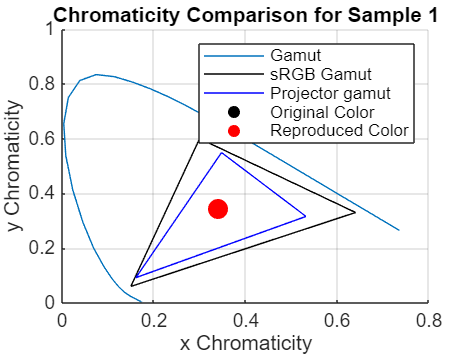

% Sample with a low delta Eab in whatever column of matrix (important,
% matrix not vector)
[~, best_sample_idx] = min(deltaE_clipped); 

% Extract XYZ values for the original and reproduced color
XYZ_original = XYZ_ref(:, best_sample_idx);
XYZ_reproduced = XYZ_projected_clipped(:, best_sample_idx);

% Convert to xy chromaticity coordinates
xy_original = XYZ_original(1:2) / sum(XYZ_original);
xy_reproduced = XYZ_reproduced(1:2) / sum(XYZ_reproduced);

% Plot chromaticity coordinates
figure;
hold on;
plot_chrom_sRGB(ACRT); % Display projector gamut
% Enter scatterplot elements (dots)
scatter(xy_original(1), xy_original(2), 100, 'k', 'filled'); % Original color
scatter(xy_reproduced(1), xy_reproduced(2), 100, 'r', 'filled'); % Reproduced color
legend('Gamut', 'sRGB Gamut', 'Projector gamut' , 'Original Color', 'Reproduced Color');
title(sprintf('Chromaticity Comparison for Sample %d', best_sample_idx));
xlabel('x Chromaticity');
ylabel('y Chromaticity');
grid on;
hold off;


% Display numerical chromaticity values (coordinates) & diffrences
fprintf('Chromaticity (xy) of Original Sample %d: (%.3f, %.3f)\n', best_sample_idx, xy_original(1), xy_original(2));

Chromaticity (xy) of Original Sample 1: (0.341, 0.345)


fprintf('Chromaticity (xy) of Reproduced Sample %d: (%.3f, %.3f)\n', best_sample_idx, xy_reproduced(1), xy_reproduced(2));

Chromaticity (xy) of Reproduced Sample 1: (0.342, 0.345)


fprintf('Perceptual color difference delta Eab: %.2f\n', deltaE_clipped(best_sample_idx));

Perceptual color difference delta Eab: 0.03


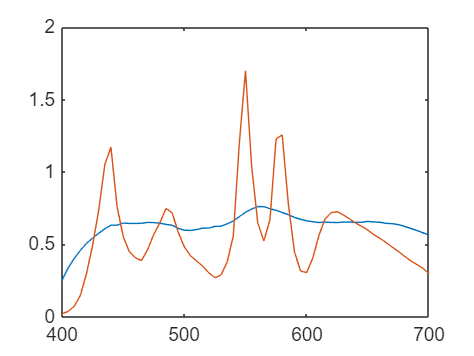


plot(waverange, chips20(1,:).* CIED65)
hold on
plot(waverange, SRGB_clipped(:,1))